# Suspension Trade Study

## User Editable Variables

config = "standard";
FR =0;
RR =0;
FL =0;
RL =0.3;

## Constants

l_spr = 0.5; % spring length (unloaded)
k_spr = 1000; % spring coefficient
m_v = 251; % vehicle mass
m_a = 170; % astronaut mass
m_p = 80; % payload mass
g = 1.62; % lunar gravitational constant
w_rover = 1.6; % rover width
n = 4; % fixed - won't adjust for more wheels

## Config Variables

if config == "standard"
    W = (m_v+m_a)*g;
    l_rover = 2;
    x_offset = 0.115;
    z_offset = 0.87;
    color = '#0072BD';
elseif config == "extended"
    W = (m_v+2*m_a)*g;
    l_rover = 2.6;
    x_offset = -0.156;
    z_offset = 0.96;
    color = '#77AC30';
end

obstacles = [FR,RR,FL,RL];

## Rover Transforms

X_wv = [l_rover/2 -l_rover/2 l_rover/2 -l_rover/2
        w_rover/2 w_rover/2 -w_rover/2 -w_rover/2
        0 0 0 0
        1 1 1 1];

X_cgv = [x_offset; 
         0;
         z_offset;
         1];

syms theta phi zc

T_vo = [cos(phi) 0 sin(phi) 0;
        -sin(phi)*sin(theta) cos(theta) cos(theta)*sin(theta) 0;
        -sin(phi)*cos(theta) -sin(theta) cos(theta)*cos(theta) zc;
        0 0 0 1];
    
X_wo = T_vo*X_wv;
X_cgo = T_vo*X_cgv;

F_spr = [k_spr*(l_spr - X_wo(3,1) + obstacles(1))
         k_spr*(l_spr - X_wo(3,2) + obstacles(2))
         k_spr*(l_spr - X_wo(3,3) + obstacles(3))
         k_spr*(l_spr - X_wo(3,4) + obstacles(4))];

## Constraint Equations

sum1 = 0;
sum2 = 0;
sum3 = 0;
for i = 1:4
    sum1 = sum1 + F_spr(i);
    sum2 = sum2 + F_spr(i)*X_wo(1,i);
    sum3 = sum3 + F_spr(i)*X_wo(2,i);
end

eq1 = sum1 == W;
eq2 = sum2 + W*X_cgo(1) == 0;
eq3 = sum3 + W*X_cgo(2) == 0;

solution = vpasolve([eq1,eq2,eq3],[theta,phi,zc]);

## Resulting Transforms

X_wc_ = double(subs(X_wo,[theta,phi,zc],[solution.theta,solution.phi,solution.zc]));
F_w = double(subs(F_spr,[theta,phi,zc],[solution.theta,solution.phi,solution.zc]));

## Results

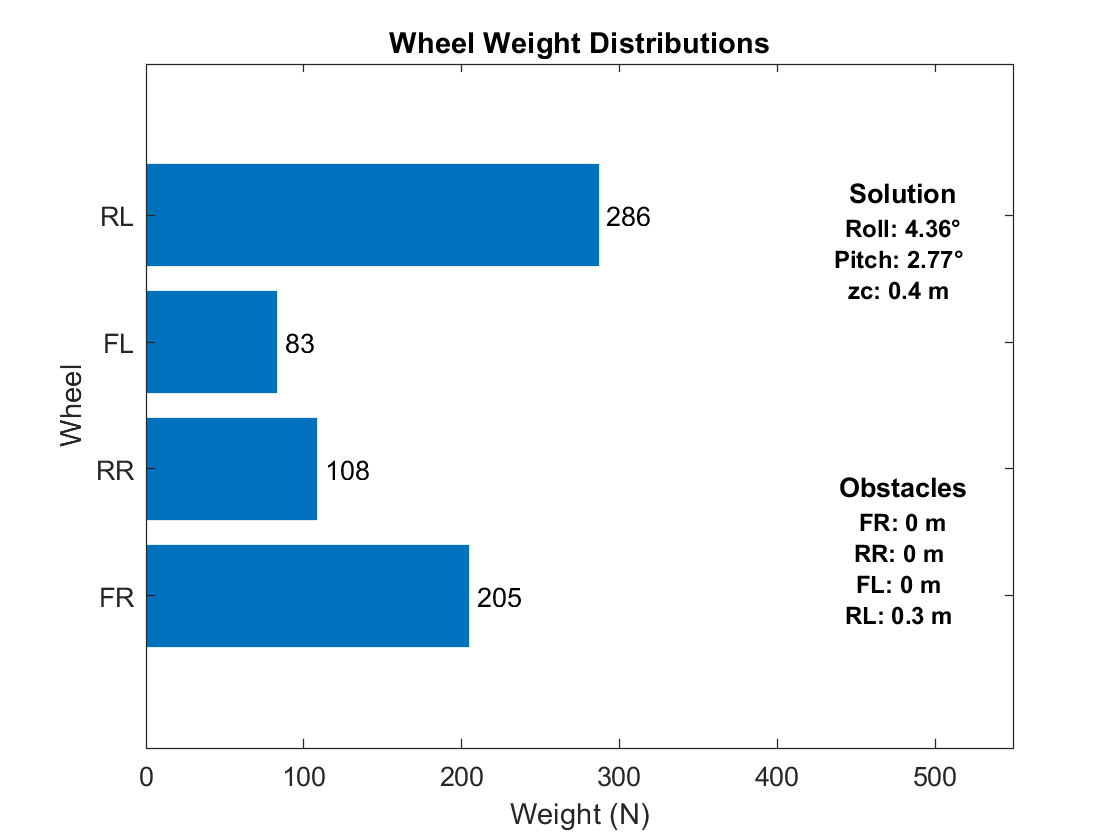

bh = barh(F_w,'EdgeColor',color,'FaceColor',color);
yticklabels({'FR','RR','FL','RL'})
xtips = bh(1).YEndPoints + 5;
ytips = bh(1).XEndPoints;
xlim([0 550])
labels = string(round(bh(1).YData));
text(xtips,ytips,labels,'VerticalAlignment','middle')
title('Wheel Weight Distributions')
xlabel('Weight (N)')
ylabel('Wheel')
roll = rad2deg(double(solution.theta));
pitch = rad2deg(double(solution.phi));
zc_ = double(solution.zc);

dim = [.65 .5 .3 .3];
str = {'\fontsize{10} \bf Solution'
       '\fontsize{9} \bf Roll: '+ string(round(roll,2)) + char(176)
       '\bf Pitch: '+ string(round(pitch,2)) + char(176)
       '\bf zc: '+ string(round(zc_,2))+ ' m'};
annotation('textbox',dim,'String',str,'FitBoxToText','on','HorizontalAlignment','center','EdgeColor','none');
dim = [.65 0.15 .3 .3];
str = {'\fontsize{10} \bf Obstacles'
       '\fontsize{9} \bf FR: ' + string(FR) + ' m'
       '\bf RR: ' + string(RR) + ' m'
       '\bf FL: ' + string(FL) + ' m'
       '\bf RL: ' + string(RL) + ' m'};
annotation('textbox',dim,'String',str,'FitBoxToText','on','HorizontalAlignment','center','EdgeColor','none');